# XTD_A6: Interval Decoding Port Entry Decode D TransMat

% NOTE: This is written to run with PokeIn Alignment ONLY

% load('.\XTD_WT_PI_PO_RawLFP.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);

trlStrtWinDur = 2800;

meanType = 'mean';
% meanType = 'median';

smoothYN = 0;
% smoothYN = 1;
% smoothYN = 2;

## Compile Data

% Interval Trained Model Decoding & Decoding Peaks
intTrn_TransMat = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
intTrn_TransMat_PeakLocs = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
intTrn_TransMat_PeakVals = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
intTrn_TransMat_PeakWids = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
% Pre-Decision Trained Model Decoding & Decoding Peaks
preDec_TransMat = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
preDec_TransMat_PeakLocs = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
preDec_TransMat_PeakVals = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
preDec_TransMat_PeakWids = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
% Post-Decision Trained Model Decoding & Decoding Peaks
pstDec_TransMat = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
pstDec_TransMat_PeakLocs = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
pstDec_TransMat_PeakVals = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);
pstDec_TransMat_PeakWids = cell(mlb.seqLength, mlb.seqLength, mlb.seqLength);

% Step through each animal's performance
for ani = 1:length(fileDirs)
    for testPos = 1:mlb.seqLength
        % Pull out temporary animal data
        curAni_TrialInfo_Pos = xtd_TrialInfo_POS{testPos,ani};
        curAni_TrialInfo_All = xtd_TrialInfo_FULL{ani};
        curAni_SeqStarts = find([curAni_TrialInfo_All.Position]==1);
        curAni_TrialMask = mask_Trial{testPos,ani};
        if strcmp(alignment{1}, 'PokeIn')
            curAni_IntMask = mask_PreInt{testPos,ani};
            curAni_IntMaskCON = mask_PreIntCON{testPos,ani};
        else
            curAni_IntMask = mask_PstInt{testPos,ani};
            curAni_IntMaskCON =  mask_PstIntCON{testPos,ani};
        end
        %     curAni_D = xtd_D(testPos,:,ani);
        curAni_D = xtd_HR(testPos,:,ani);
        % Step through each trial
        for trl = 1:length(curAni_TrialInfo_Pos)
            %         if (curAni_TrialInfo_Pos(trl).Performance ~= 1)
            if (curAni_TrialInfo_Pos(trl).Performance == 1)
                % Identify the sequence the 4 comes from
                curSeqStart = curAni_SeqStarts(find(curAni_SeqStarts<=curAni_TrialInfo_Pos(trl).TrialNum,1,'last'));
                curSeqVect = [curAni_TrialInfo_All(curSeqStart:curAni_TrialInfo_Pos(trl).TrialNum).Odor];
                osLog = mod(curSeqVect,10)~=1:testPos;
                if sum(osLog)==0
                    osPos = testPos;
                    osOdr = testPos;
                else
                    osPos = find(osLog);
                    osOdr = mod(curSeqVect(osPos),10);
                end
                                
                % Create a trial start window mask
                if strcmp(alignment{1}, 'PokeIn')
                    curTrlStrtNdx = find(curAni_TrialMask(:,trl),1,'first');
                else
                    curTrlStrtNdx = find(curAni_TrialMask(:,trl),1,'last');
                end
                replayMask = false(size(mlb.obsvTimeVect));
                replayMask(curTrlStrtNdx-(trlStrtWinDur/2/mlb.dsRate):curTrlStrtNdx+((trlStrtWinDur/2/mlb.dsRate)-1)) = true;
                intTrn_Replay = nan(sum(replayMask), mlb.seqLength);
                intTrn_Replay_PeakLocs = nan(1, mlb.seqLength);
                intTrn_Replay_PeakVals = nan(1, mlb.seqLength);
                intTrn_Replay_PeakWids = nan(1, mlb.seqLength);
                preDec_Replay = nan(sum(replayMask), mlb.seqLength);
                preDec_Replay_PeakLocs = nan(1, mlb.seqLength);
                preDec_Replay_PeakVals = nan(1, mlb.seqLength);
                preDec_Replay_PeakWids = nan(1, mlb.seqLength);
                pstDec_Replay = nan(sum(replayMask), mlb.seqLength);
                pstDec_Replay_PeakLocs = nan(1, mlb.seqLength);
                pstDec_Replay_PeakVals = nan(1, mlb.seqLength);
                pstDec_Replay_PeakWids = nan(1, mlb.seqLength);

                if strcmp(alignment{1}, 'PokeIn')
                    if testPos~=1
                        curTrl_IntMask = find(curAni_IntMask(:,trl),1,'first');
                    else
                        curTrl_IntMask = find(curAni_IntMask(:,trl),1,'last')-(1000/mlb.dsRate);
                    end
%                     curTrl_PreDecMask = find(curAni_IntMask(:,trl),1,'last')+6; % HC Decoding Window
                    curTrl_PreDecMask = find(curAni_IntMask(:,trl),1,'last')+9; % Pre-Decision Window
                    curTrl_PstDecMask = find(curAni_IntMask(:,trl),1,'last')+17; % Post-Decision Window
                else
                    if testPos~=4
                        curTrl_IntMask = find(curAni_IntMask(:,trl),1,'last');
                    else
                        curTrl_IntMask = find(curAni_IntMask(:,trl),1,'first') + (1000/mlb.dsRate);
                    end
%                     curTrl_PreDecMask = find(curAni_IntMask(:,trl),1,'last')+6; % HC Decoding Window
                    curTrl_PreDecMask = find(curAni_IntMask(:,trl),1,'first')+9; % Pre-Decision Window
                    curTrl_PstDecMask = find(curAni_IntMask(:,trl),1,'first')+17; % Post-Decision Window
                end
                for pos = 1:mlb.seqLength
                    replayTime = mlb.obsvTimeVect(replayMask);
                    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                    % Examine Interval Trained Model
                    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                    if smoothYN == 0
                        intTrn_Replay(:,pos) = curAni_D{pos}(replayMask, curTrl_IntMask,trl);
                    elseif smoothYN == 1
                        intTrn_Replay(:,pos) = smooth(curAni_D{pos}(replayMask, curTrl_IntMask,trl));
                    elseif smoothYN == 2
                        intTrn_Replay(:,pos) = smooth(curAni_D{pos}(replayMask, curTrl_IntMask,trl), 'lowess');
                    end
                    [itPks,itLocs,itWid,itProm] = findpeaks(intTrn_Replay(:,pos),'minpeakdistance', mlb.binSize/mlb.dsRate);
%                     pkMask = itPks>0.25;
                    pkMask = itPks>0;
%                     locMask = itLocs<(find(mlb.obsvTimeVect(replayMask)==0));
%                     locMask = itLocs>(find(mlb.obsvTimeVect(replayMask)==0));
                    locMask = itLocs>mlb.obsvTimeVect(1);
                    itPks(~pkMask|~locMask) = [];
                    itLocs(~pkMask|~locMask) = [];
                    itWid(~pkMask|~locMask) = [];
                    itProm(~pkMask|~locMask) = [];
                    if ~isempty(itPks)
%                         itFeatWeightPeaks = itPks.*itProm;
                        itFeatWeightPeaks = itPks.*itWid.*itProm;
                        tempPeak = itLocs(itFeatWeightPeaks==max(itFeatWeightPeaks));
                        intTrn_Replay_PeakLocs(pos) = replayTime(tempPeak);
                        intTrn_Replay_PeakVals(pos) = itPks(itFeatWeightPeaks==max(itFeatWeightPeaks));
                        intTrn_Replay_PeakWids(pos) = itWid(itFeatWeightPeaks==max(itFeatWeightPeaks));
                    else
                        intTrn_Replay_PeakLocs(pos) = nan;
                        intTrn_Replay_PeakVals(pos) = nan;
                        intTrn_Replay_PeakWids(pos) = nan;
                    end
                    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                    % Examine Pre-Decision Trained Model
                    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                    if smoothYN == 0
                        preDec_Replay(:,pos) = curAni_D{pos}(replayMask, curTrl_PreDecMask,trl);
                    elseif smoothYN == 1
                        preDec_Replay(:,pos) = smooth(curAni_D{pos}(replayMask, curTrl_PreDecMask,trl));
                    elseif smoothYN == 2
                        preDec_Replay(:,pos) = smooth(curAni_D{pos}(replayMask, curTrl_PreDecMask,trl), 'lowess');
                    end
                    [prPks,prLocs,prWid,prProm] = findpeaks(preDec_Replay(:,pos),'minpeakdistance', mlb.binSize/mlb.dsRate);
%                     pkMask = prPks>0.25;
                    pkMask = prPks>0;
%                     locMask = prLocs<(find(mlb.obsvTimeVect(replayMask)==0));
%                     locMask = prLocs>(find(mlb.obsvTimeVect(replayMask)==0));
                    locMask = prLocs>mlb.obsvTimeVect(1);
                    prPks(~pkMask|~locMask) = [];
                    prLocs(~pkMask|~locMask) = [];
                    prWid(~pkMask|~locMask) = [];
                    prProm(~pkMask|~locMask) = [];
                    if ~isempty(prPks)
%                         featWeightPeaks = prPks.*prProm;
                        prFeatWeightPeaks = prPks.*prWid.*prProm;
                        tempPeak = prLocs(prFeatWeightPeaks==max(prFeatWeightPeaks));
                        preDec_Replay_PeakLocs(pos) = replayTime(tempPeak);
                        preDec_Replay_PeakVals(pos) = prPks(prFeatWeightPeaks==max(prFeatWeightPeaks));
                        preDec_Replay_PeakWids(pos) = prWid(prFeatWeightPeaks==max(prFeatWeightPeaks));
                    else
                        preDec_Replay_PeakLocs(pos) = nan;
                        preDec_Replay_PeakVals(pos) = nan;
                        preDec_Replay_PeakWids(pos) = nan;
                    end
                    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                    % Examine Post-Decision Trained Model
                    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                    if smoothYN == 0
                        pstDec_Replay(:,pos) = curAni_D{pos}(replayMask, curTrl_PstDecMask,trl);
                    elseif smoothYN == 1
                        pstDec_Replay(:,pos) = smooth(curAni_D{pos}(replayMask, curTrl_PstDecMask,trl));
                    elseif smoothYN == 2
                        pstDec_Replay(:,pos) = smooth(curAni_D{pos}(replayMask, curTrl_PstDecMask,trl), 'lowess');
                    end
                    [ptPks,ptLocs,ptWid,ptProm] = findpeaks(pstDec_Replay(:,pos),'minpeakdistance', mlb.binSize/mlb.dsRate);
%                     pkMask = ptPks>0.25;
                    pkMask = ptPks>0;
%                     locMask = prLocs<(find(mlb.obsvTimeVect(replayMask)==0));
%                     locMask = prLocs>(find(mlb.obsvTimeVect(replayMask)==0));
                    locMask = ptLocs>mlb.obsvTimeVect(1);
                    ptPks(~pkMask|~locMask) = [];
                    ptLocs(~pkMask|~locMask) = [];
                    ptWid(~pkMask|~locMask) = [];
                    ptProm(~pkMask|~locMask) = [];
                    if ~isempty(ptPks)
%                         featWeightPeaks = ptPks.*prProm;
                        ptFeatWeightPeaks = ptPks.*ptWid.*ptProm;
                        tempPeak = ptLocs(ptFeatWeightPeaks==max(ptFeatWeightPeaks));
                        pstDec_Replay_PeakLocs(pos) = replayTime(tempPeak);
                        pstDec_Replay_PeakVals(pos) = ptPks(ptFeatWeightPeaks==max(ptFeatWeightPeaks));
                        pstDec_Replay_PeakWids(pos) = ptWid(ptFeatWeightPeaks==max(ptFeatWeightPeaks));
                    else
                        pstDec_Replay_PeakLocs(pos) = nan;
                        pstDec_Replay_PeakVals(pos) = nan;
                        pstDec_Replay_PeakWids(pos) = nan;
                    end                    
                end
                intTrn_TransMat{osOdr,osPos,testPos} = cat(3,intTrn_TransMat{osOdr,osPos,testPos}, intTrn_Replay);
                intTrn_TransMat_PeakLocs{osOdr,osPos,testPos} = cat(3,intTrn_TransMat_PeakLocs{osOdr,osPos,testPos}, intTrn_Replay_PeakLocs);
                intTrn_TransMat_PeakVals{osOdr,osPos,testPos} = cat(3,intTrn_TransMat_PeakVals{osOdr,osPos,testPos}, intTrn_Replay_PeakVals);
                intTrn_TransMat_PeakWids{osOdr,osPos,testPos} = cat(3,intTrn_TransMat_PeakWids{osOdr,osPos,testPos}, intTrn_Replay_PeakWids);
                preDec_TransMat{osOdr,osPos,testPos} = cat(3, preDec_TransMat{osOdr,osPos,testPos}, preDec_Replay);
                preDec_TransMat_PeakLocs{osOdr,osPos,testPos} = cat(3, preDec_TransMat_PeakLocs{osOdr,osPos,testPos}, preDec_Replay_PeakLocs);
                preDec_TransMat_PeakVals{osOdr,osPos,testPos} = cat(3, preDec_TransMat_PeakVals{osOdr,osPos,testPos}, preDec_Replay_PeakVals);
                preDec_TransMat_PeakWids{osOdr,osPos,testPos} = cat(3, preDec_TransMat_PeakWids{osOdr,osPos,testPos}, preDec_Replay_PeakWids);
                pstDec_TransMat{osOdr,osPos,testPos} = cat(3, pstDec_TransMat{osOdr,osPos,testPos}, pstDec_Replay);
                pstDec_TransMat_PeakLocs{osOdr,osPos,testPos} = cat(3, pstDec_TransMat_PeakLocs{osOdr,osPos,testPos}, pstDec_Replay_PeakLocs);
                pstDec_TransMat_PeakVals{osOdr,osPos,testPos} = cat(3, pstDec_TransMat_PeakVals{osOdr,osPos,testPos}, pstDec_Replay_PeakVals);
                pstDec_TransMat_PeakWids{osOdr,osPos,testPos} = cat(3, pstDec_TransMat_PeakWids{osOdr,osPos,testPos}, pstDec_Replay_PeakWids);
            end
        end
    end
end

trialLIGHTlat = lat_PrtLight(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = lat_TrlStart(:);
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = lat_RwdSig(:);
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = lat_TrlEnd(:);
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = lat_Rwd(:);
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = lat_NextTrl(:);
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = lat_PrevTrl(:);
% prevTrlLats = cell2mat(prevTrlLats(:)');

## Plot Things

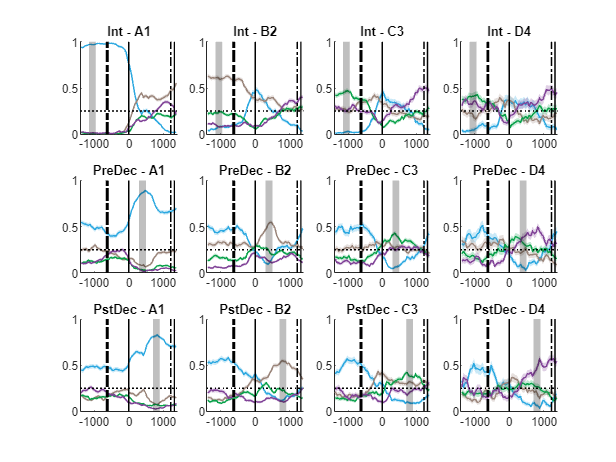

windowXticks = (trlStrtWinDur/2*-1:mlb.dsRate:(trlStrtWinDur/2-mlb.dsRate)) + mlb.dsRate/2;
figure;
for testPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,1));
        mlb.PlotMeanVarLine(windowXticks, intTrn_TransMat{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:));
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,2));
        mlb.PlotMeanVarLine(windowXticks, preDec_TransMat{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:));
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,3));
        mlb.PlotMeanVarLine(windowXticks, pstDec_TransMat{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:));
    end
    for p = 1:3
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,p));
        set(gca, 'ylim', [0 1], 'xlim', [trlStrtWinDur/-2 trlStrtWinDur/2]);
        if pos~=1
            plot(repmat(median(cell2mat(lat_PrtLight(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-.k', 'linewidth', 2);
            %             plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
        end
        plot(repmat(median(cell2mat(lat_TrlStart(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-k', 'linewidth', 1);
        plot(repmat(median(cell2mat(lat_RwdSig(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-.k', 'linewidth', 1);
        plot(repmat(median(cell2mat(lat_TrlEnd(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-k', 'linewidth', 1);
%         plot(repmat(median(cell2mat(lat_Rwd(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), ':k', 'linewidth', 1);
        plot(get(gca,'xlim'), [0.25 0.25],':k','linewidth', 1);
%         if strcmp(endTrialBound, 'RWD')
%             plot( repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
%         elseif strcmp(endTrialBound, 'PO')
%             plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
%         elseif strcmp(endTrialBound, 'RS')
%             plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
%         end

        if p==1
            patch([mlb.obsvTimeVect(curTrl_IntMask)*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(curTrl_IntMask)*mlb.sampleRate + mlb.binSize/2,...
                mlb.obsvTimeVect(curTrl_IntMask)*mlb.sampleRate + mlb.binSize/2, mlb.obsvTimeVect(curTrl_IntMask)*mlb.sampleRate - mlb.binSize/2],...
                [0 0 1 1], 'k', 'facealpha', 0.25, 'linestyle', 'none');
            title(sprintf('Int - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==2

            patch([mlb.obsvTimeVect(curTrl_PreDecMask)*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(curTrl_PreDecMask)*mlb.sampleRate + mlb.binSize/2,...
                mlb.obsvTimeVect(curTrl_PreDecMask)*mlb.sampleRate + mlb.binSize/2, mlb.obsvTimeVect(curTrl_PreDecMask)*mlb.sampleRate - mlb.binSize/2],...
                [0 0 1 1], 'k', 'facealpha', 0.25, 'linestyle', 'none');
            title(sprintf('PreDec - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==3
            patch([mlb.obsvTimeVect(curTrl_PstDecMask)*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(curTrl_PstDecMask)*mlb.sampleRate + mlb.binSize/2,...
                mlb.obsvTimeVect(curTrl_PstDecMask)*mlb.sampleRate + mlb.binSize/2, mlb.obsvTimeVect(curTrl_PstDecMask)*mlb.sampleRate - mlb.binSize/2],...
                [0 0 1 1], 'k', 'facealpha', 0.25, 'linestyle', 'none');
            title(sprintf('PstDec - %s%i',mlb.Rosetta{testPos},testPos));
        end
    end      
end

## Plot Peak Vals

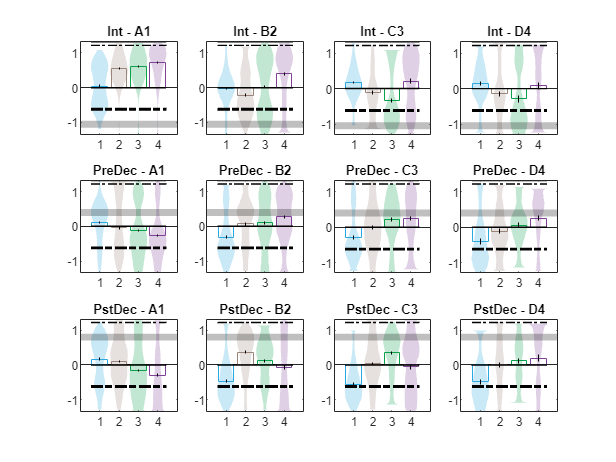

windowXticks = (trlStrtWinDur/2*-1:mlb.dsRate:(trlStrtWinDur/2-mlb.dsRate)) + mlb.dsRate/2;
figure;
for testPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,1));
        mlb.PlotMeanVarViolin(decPos, intTrn_TransMat_PeakLocs{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,2));
        mlb.PlotMeanVarViolin(decPos, preDec_TransMat_PeakLocs{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,3));
        mlb.PlotMeanVarViolin(decPos, pstDec_TransMat_PeakLocs{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
    end
    for p = 1:3
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,p));
        set(gca, 'xlim', [0 mlb.seqLength+1], 'xtick', 1:mlb.seqLength, 'ylim', [trlStrtWinDur/-2 trlStrtWinDur/2]);
        axis tight
        if pos~=1
            plot(get(gca,'xlim'), repmat(median(cell2mat(lat_PrtLight(pos,:)), 'omitnan'), [1,2]), '-.k', 'linewidth', 2);
        end
        plot(get(gca,'xlim'), repmat(median(cell2mat(lat_TrlStart(pos,:)), 'omitnan'), [1,2]), '-k', 'linewidth', 1);
        plot(get(gca,'xlim'), repmat(median(cell2mat(lat_RwdSig(pos,:)), 'omitnan'), [1,2]), '-.k', 'linewidth', 1);
        plot(get(gca,'xlim'), repmat(median(cell2mat(lat_TrlEnd(pos,:)), 'omitnan'), [1,2]), '-k', 'linewidth', 1);
%         plot(get(gca,'xlim'), repmat(median(cell2mat(lat_Rwd(pos,:)), 'omitnan'), [1,2]), ':k', 'linewidth', 1);
%         if strcmp(endTrialBound, 'RWD')
%             plot(get(gca,'xlim'),  repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
%         elseif strcmp(endTrialBound, 'PO')
%             plot(get(gca,'xlim'), repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
%         elseif strcmp(endTrialBound, 'RS')
%             plot(get(gca,'xlim'), repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
%         end

        if p==1
            patch([0 mlb.seqLength+1 mlb.seqLength+1, 0],...
                [mlb.obsvTimeVect(curTrl_IntMask) - mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curTrl_IntMask) - mlb.binSize/(2*mlb.sampleRate),...
                mlb.obsvTimeVect(curTrl_IntMask) + mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curTrl_IntMask) + mlb.binSize/(2*mlb.sampleRate)],...
                'k', 'facealpha', 0.25, 'linestyle', 'none');
            title(sprintf('Int - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==2
            patch([0 mlb.seqLength+1 mlb.seqLength+1, 0],...
                [mlb.obsvTimeVect(curTrl_PreDecMask) - mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curTrl_PreDecMask) - mlb.binSize/(2*mlb.sampleRate),...
                mlb.obsvTimeVect(curTrl_PreDecMask) + mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curTrl_PreDecMask) + mlb.binSize/(2*mlb.sampleRate)],...
                'k', 'facealpha', 0.25, 'linestyle', 'none');
            title(sprintf('PreDec - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==3
            patch([0 mlb.seqLength+1 mlb.seqLength+1, 0],...
                [mlb.obsvTimeVect(curTrl_PstDecMask) - mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curTrl_PstDecMask) - mlb.binSize/(2*mlb.sampleRate),...
                mlb.obsvTimeVect(curTrl_PstDecMask) + mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curTrl_PstDecMask) + mlb.binSize/(2*mlb.sampleRate)],...
                'k', 'facealpha', 0.25, 'linestyle', 'none');
            title(sprintf('PstDec - %s%i',mlb.Rosetta{testPos},testPos));
        end
    end      
end

## Plot Widths

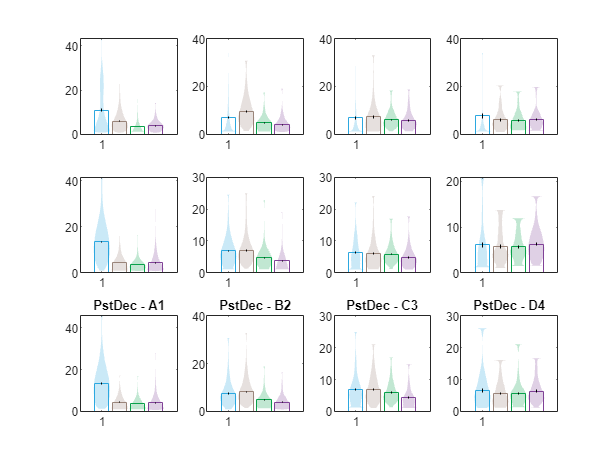

windowXticks = (trlStrtWinDur/2*-1:mlb.dsRate:(trlStrtWinDur/2-mlb.dsRate)) + mlb.dsRate/2;
figure;
for testPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,1));
        mlb.PlotMeanVarViolin(decPos, intTrn_TransMat_PeakWids{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,2));
        mlb.PlotMeanVarViolin(decPos, preDec_TransMat_PeakWids{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,3));
        mlb.PlotMeanVarViolin(decPos, pstDec_TransMat_PeakWids{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
    end
    for p = 1:3
        
        if p==1
            
            title(sprintf('Int - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==2
            
            title(sprintf('PreDec - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==3
          
            title(sprintf('PstDec - %s%i',mlb.Rosetta{testPos},testPos));
        end
    end      
end

## Plot Vals

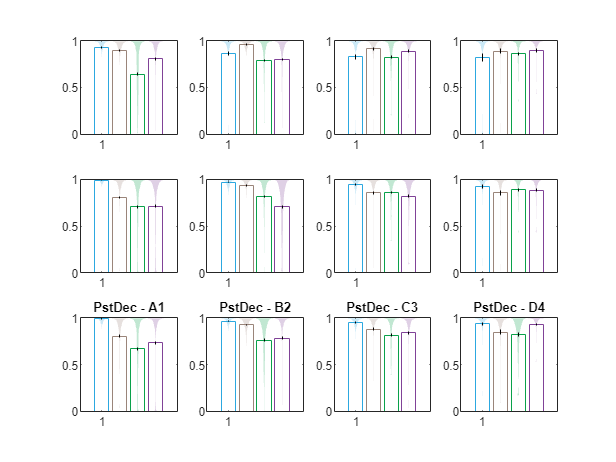


figure;
for testPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,1));
        mlb.PlotMeanVarViolin(decPos, intTrn_TransMat_PeakVals{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,2));
        mlb.PlotMeanVarViolin(decPos, preDec_TransMat_PeakVals{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
        subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3],testPos,3));
        mlb.PlotMeanVarViolin(decPos, pstDec_TransMat_PeakVals{testPos,testPos,testPos}(:,decPos,:),3,0,mlb.PositionColors(decPos,:), meanType);
    end
    for p = 1:3
        
        if p==1
            
            title(sprintf('Int - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==2
            
            title(sprintf('PreDec - %s%i',mlb.Rosetta{testPos},testPos));
        elseif p==3
          
            title(sprintf('PstDec - %s%i',mlb.Rosetta{testPos},testPos));
        end
    end      
end

## Look at differences in peaks

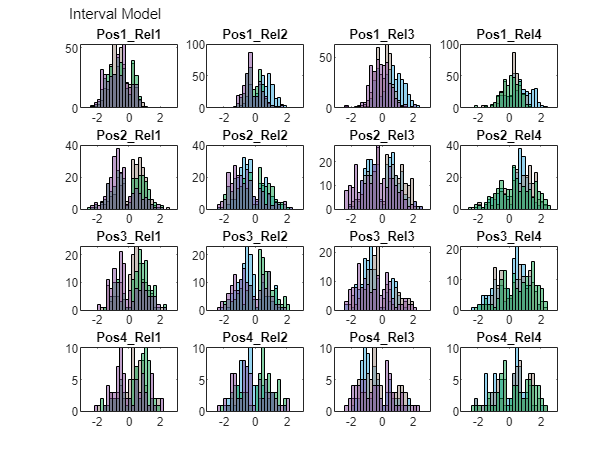

histBins = trlStrtWinDur/-1000 : 0.2: trlStrtWinDur/1000;

figure; 
for trlPos = 1:mlb.seqLength
    curPks = squeeze(intTrn_TransMat_PeakLocs{trlPos,trlPos,trlPos});
    for decPos = 1:mlb.seqLength
        subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], decPos, trlPos));
        for diffPos = 1:mlb.seqLength
            if diffPos ~= decPos
                histogram(curPks(decPos,:) - curPks(diffPos,:), histBins, 'FaceColor', mlb.PositionColors(diffPos,:), 'FaceAlpha', 0.5);
                hold on;
            end
        end
        if decPos == 1
            ylabel(sprintf('Pos%i Trials', trlPos));
        end
        title(sprintf('Rel%i', decPos), 'interpreter', 'none');
    end
end
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Interval Model', 'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');

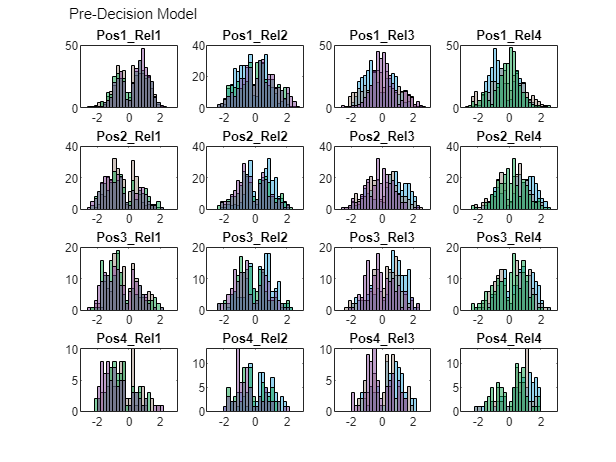


figure; 
for trlPos = 1:mlb.seqLength
    curPks = squeeze(preDec_TransMat_PeakLocs{trlPos,trlPos,trlPos});
    for decPos = 1:mlb.seqLength
        subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], decPos, trlPos));
        for diffPos = 1:mlb.seqLength
            if diffPos ~= decPos
                histogram(curPks(decPos,:) - curPks(diffPos,:), histBins, 'FaceColor', mlb.PositionColors(diffPos,:), 'FaceAlpha', 0.5);
                hold on;
            end
        end
        if decPos == 1
            ylabel(sprintf('Pos%i Trials', trlPos));
        end
        title(sprintf('Rel%i', decPos), 'interpreter', 'none');
    end
end
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Pre-Decision Model', 'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');

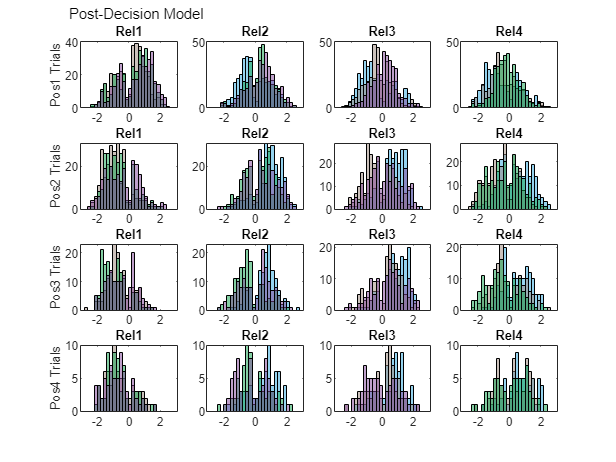


figure; 
for trlPos = 1:mlb.seqLength
    curPks = squeeze(pstDec_TransMat_PeakLocs{trlPos,trlPos,trlPos});
    for decPos = 1:mlb.seqLength
        subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], decPos, trlPos));
        for diffPos = 1:mlb.seqLength
            if diffPos ~= decPos
                histogram(curPks(decPos,:) - curPks(diffPos,:), histBins, 'FaceColor', mlb.PositionColors(diffPos,:), 'FaceAlpha', 0.5);
                hold on;
            end
        end
        if decPos == 1
            ylabel(sprintf('Pos%i Trials', trlPos));
        end
        title(sprintf('Rel%i', decPos), 'interpreter', 'none');
    end
end
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Post-Decision Model', 'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');